# Manipulación de modelos

**Autor: German Preciat, Universidad de Guadalajara**

## INTRODUCCIÓN

En este tutorial, haremos una manipulación con un modelo simple de las primeras reacciones de la ruta metabólica de la glucólisis como se creó en el tutorial "Creación de modelos".

La glucólisis es la vía metabólica que ocurre en la mayoría de los organismos en el citosol de la célula. Primero, usaremos el comienzo de esa vía para crear una red metabólica simple basada en restricciones (Figura 1).

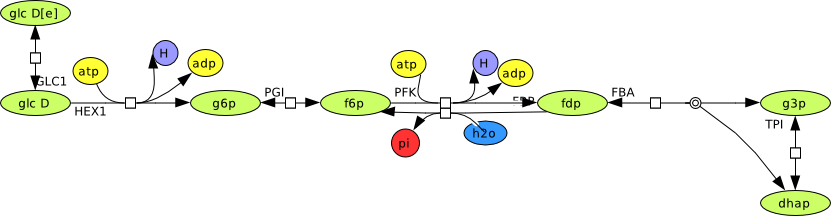

Figura 1: Una pequeña red metabólica que consta de siete reacciones en la vía de la glucólisis.

Al comienzo de la reconstrucción, el paso inicial es evaluar la integridad del proyecto de reconstrucción. Además, se necesita una evaluación de la precisión: verificar la necesidad de cada reacción y metabolito, la precisión de la estequiometría y la dirección y reversibilidad de las reacciones.

Las estructuras y reacciones de los metabolitos provienen de la base de datos Virtual Metabolic Human (VMH, [http://vmh.life](http://vmh.life/)).

- Después de crear o cargar el modelo y para simular diferentes condiciones del modelo, se puede modificar el modelo, como por ejemplo:

- Crear, agregar y manejar reacciones;

- Adición de reacciones de intercambio, sumidero y demanda;

- Alteración de los límites de reacción;

- Reacciones de alteración;

- Eliminación de reacciones y metabolitos;

- Búsqueda de duplicados y comparación de dos modelos;

- Cambiar el objetivo del modelo;

- Cambiar la dirección de la(s) reacción(es);

- Creación de asociaciones de reacciones génicas ('GPR');

- Extracción de una subred

## CONFIGURACIÓN DEL EQUIPO

Iniciar CobraToolbox

initCobraToolbox(false)



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2024
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.13.3).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)...

## PROCEDIMIENTO

## Generar una red

Un modelo metabólico basado en restricciones contiene la matriz estequiométrica ($$S$) con reacciones y metabolitos [1].

$$S$ es una representación estequiométrica de las redes metabólicas correspondientes a las reacciones en la vía bioquímica. En cada columna de la $$S$ es una reaccion bioquimica ($$n$) y en cada fila hay un metabolito preciso($$m$). Hay un coeficiente estequiométrico de cero, lo que significa que el metabolito no participa en esa reacción distinta. El coeficiente también puede ser positivo cuando se produce el metabolito apropiado, o negativo para cada metabolito consumido. [1].

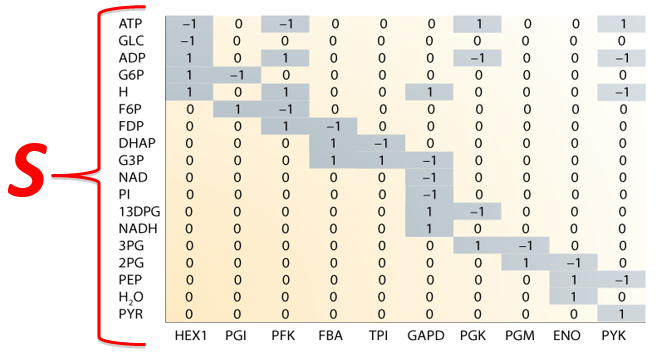

Genere un modelo usando la función `createModel()`:

ReactionFormulas = {'glc_D[e]  -> glc_D[c]',...
    'glc_D[c] + atp[c]  -> h[c] + adp[c] + g6p[c]',...
    'g6p[c]  <=> f6p[c]',...
    'atp[c] + f6p[c]  -> h[c] + adp[c] + fdp[c]',...
    'fdp[c] + h2o[c]  -> f6p[c] + pi[c]',...
    'fdp[c]  -> g3p[c] + dhap[c]',...
    'dhap[c]  -> g3p[c]'};
ReactionNames = {'GLCt1r', 'HEX1', 'PGI', 'PFK', 'FBP', 'FBA', 'TPI'};
lowerbounds = [-20, 0, -20, 0, 0, -20, -20];
upperbounds = [20, 20, 20, 20, 20, 20, 20];
model = createModel(ReactionNames, ReactionNames, ReactionFormulas,...
                   'lowerBoundList', lowerbounds, 'upperBoundList', upperbounds);

Adding the following Metabolites to the model:
adp[c]
atp[c]
dhap[c]
f6p[c]
fdp[c]
g3p[c]
g6p[c]
glc_D[c]
glc_D[e]
h2o[c]
h[c]
pi[c]
addMultipleReactions: Adding the following reactions to the model:
GLCt1r	glc_D[e] 	<=>	glc_D[c] 
HEX1	atp[c] + glc_D[c] 	->	adp[c] + g6p[c] + h[c] 
PGI	g6p[c] 	<=>	f6p[c] 
PFK	atp[c] + f6p[c] 	->	adp[c] + fdp[c] + h[c] 
FBP	fdp[c] + h2o[c] 	->	f6p[c] + pi[c] 
FBA	fdp[c] 	<=>	dhap[c] + g3p[c] 
TPI	dhap[c] 	<=>	g3p[c] 


Ahora podemos echar un vistazo a los diferentes campos del modelo creados. La estequiometría se almacena en el $$S$ campo del modelo, que se describió anteriormente. Dado que esta es comúnmente una matriz dispersa (es decir, contiene muchos ceros), puede ser útil para su comprensión mostrar la representación completa:

full(model.S)

ans =      0     1     0     1     0     0     0
     0    -1     0    -1     0     0     0
     0     0     0     0     0     1    -1
     0     0     1    -1     1     0     0
     0     0     0     1    -1    -1     0
     0     0     0     0     0     1     1
     0     1    -1     0     0     0     0
     1    -1     0     0     0     0     0
    -1     0     0     0     0     0     0
     0     0     0     0    -1     0     0


Se requiere que un modelo conste de los campos descriptivos: model.mets y model.rxns, que representan los metabolitos y las reacciones respectivamente.

model.mets

ans = 12×1 cell array
    {'adp[c]'  }
    {'atp[c]'  }
    {'dhap[c]' }
    {'f6p[c]'  }
    {'fdp[c]'  }
    {'g3p[c]'  }
    {'g6p[c]'  }
    {'glc_D[c]'}
    {'glc_D[e]'}
    {'h2o[c]'  }
    {'h[c]'    }
    {'pi[c]'   }


model.rxns

ans = 7×1 cell array
    {'GLCt1r'}
    {'HEX1'  }
    {'PGI'   }
    {'PFK'   }
    {'FBP'   }
    {'FBA'   }
    {'TPI'   }


Los campos en un modelo COBRA son comúnmente vectores de columna, lo cual es importante tener en cuenta al escribir funciones que manipulen estos campos.

Hay algunos campos más presentes en cada modelo COBRA:

`model.lb`, que indica los límites inferiores de cada reacción, y `model.ub`, que indica el límite superior de una reacción.

% Esto muestra una matriz con nombres de reacción y límites de flujo.
[{'Reaction ID', 'Lower Bound', 'Upper Bound'};...
 model.rxns, num2cell(model.lb), num2cell(model.ub)]

ans = 8×3 cell array
    {'Reaction ID'}    {'Lower Bound'}    {'Upper Bound'}
    {'GLCt1r'     }    {[        -20]}    {[         20]}
    {'HEX1'       }    {[          0]}    {[         20]}
    {'PGI'        }    {[        -20]}    {[         20]}
    {'PFK'        }    {[          0]}    {[         20]}
    {'FBP'        }    {[          0]}    {[         20]}
    {'FBA'        }    {[        -20]}    {[         20]}
    {'TPI'        }    {[        -20]}    {[         20]}


% Esta es una función de conveniencia que hace más o menos lo mismo que la línea a
printFluxBounds(model);

Reaction ID	   Lower Bound	   Upper Bound
     GLCt1r	       -20.000	        20.000
       HEX1	         0.000	        20.000
        PGI	       -20.000	        20.000
        PFK	         0.000	        20.000
        FBP	         0.000	        20.000
        FBA	       -20.000	        20.000
        TPI	       -20.000	        20.000


Antes de comenzar a modificar el modelo, puede ser útil almacenar en el espacio de trabajo algunas de las propiedades actuales del modelo:

mets_length = length(model.mets)

mets_length = 12

rxns_length = length(model.rxns)

rxns_length = 7

## Creación, adición y manejo de reacciones.

Si queremos agregar una reacción al modelo o modificar una reacción existente, use la función addReaction.

Agregaremos al modelo algunas reacciones más de la glucólisis. Hay dos enfoques diferentes para agregar reacciones a un modelo:

- El enfoque de la fórmula

- El enfoque de la lista

**El enfoque de la fórmula**

model = addReaction(model, 'GAPDH',...
 'reactionFormula', 'g3p[c] + nad[c] + 2 pi[c] -> nadh[c] + h[c] + 13bpg[c]');
model = addReaction(model, 'PGK',...
 'reactionFormula', '13bpg[c] + adp[c] -> atp[c] + 3pg[c]', 'lowerBound', 0);
model = addReaction(model, 'PGM', 'reactionFormula', '3pg[c] <=> 2pg[c]' );

Muestre la matriz estequiométrica después de agregar reacciones (observe el enlace de ampliación cuando mueva el mouse sobre la salida para mostrar la matriz completa):

full(model.S)

ans =      0     1     0     1     0     0     0     0    -1     0
     0    -1     0    -1     0     0     0     0     1     0
     0     0     0     0     0     1    -1     0     0     0
     0     0     1    -1     1     0     0     0     0     0
     0     0     0     1    -1    -1     0     0     0     0
     0     0     0     0     0     1     1    -1     0     0
     0     1    -1     0     0     0     0     0     0     0
     1    -1     0     0     0     0     0     0     0     0
    -1     0     0     0     0     0     0     0     0     0
     0     0     0     0    -1     0     0     0     0     0


- se agrega una columna adicional (para reacción adicional) y 5 filas nuevas (para metabolitos nadh, nad, 13bpg, 2pg y 3pg)

Si desea buscar los índices de reacciones en el modelo y cambiar el orden de las reacciones seleccionadas, utilice las siguientes funciones:

rxnID = findRxnIDs(model, model.rxns)

rxnID =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


model.rxns

ans = 10×1 cell array
    {'GLCt1r'}
    {'HEX1'  }
    {'PGI'   }
    {'PFK'   }
    {'FBP'   }
    {'FBA'   }
    {'TPI'   }
    {'GAPDH' }
    {'PGK'   }
    {'PGM'   }


model = moveRxn(model, 8, 1);
model.rxns

ans = 10×1 cell array
    {'GAPDH' }
    {'GLCt1r'}
    {'HEX1'  }
    {'PGI'   }
    {'PFK'   }
    {'FBP'   }
    {'FBA'   }
    {'TPI'   }
    {'PGK'   }
    {'PGM'   }


Si bien la función moveRxn no modifica la estructura de la red, puede ser útil para mantener un modelo ordenado.

**El enfoque de la lista**

model = addReaction(model, 'GAPDH2',...
 'metaboliteList', {'g3p[c]', 'nad[c]', 'pi[c]', '13bpg[c]', 'nadh[c]', 'h[c]' },...
 'stoichCoeffList', [-1; -1; -2; 1; 1; 1], 'reversible', false);

- La función `addReaction` tiene la capacidad de reconocer reacciones duplicadas. No se agregó ninguna reacción aquí ya que se reconoce que la reacción ya existe en el modelo.

Dado que la cuarta reacción que intentamos agregar al modelo era un duplicado, el número de reacciones en el modelo solo debería aumentarse en tres y el número de metabolitos en el modelo solo debería aumentarse en cinco (13bpg, nad, nadh, 23 bpg y 2 pp).

assert(length(model.rxns) == rxns_length + 4)
assert(length(model.mets) == mets_length + 5)

## Adición de reacciones de intercambio, sumidero y demanda

Hay tres tipos específicos de reacciones en un modelo COBRA que usan y reciclan metabolitos acumulados, o producen los metabolitos requeridos:

- **Reacciones de intercambio:** son reacciones que mueven metabolitos a través de compartimentos in silico. Estos compartimentos in silico son representativos de las membranas intracelulares e intercelulares.

- **Reacciones de sumidero:** - Los metabolitos, producidos en reacciones que están fuera de un ámbito del sistema o en reacciones desconocidas, se suministran a la red con reacciones de sumidero reversibles.

- **Reacciones de demanda:** reacciones irreversibles agregadas al modelo para consumir metabolitos que se depositan en el sistema.

Hay dos formas de implementar este tipo de reacciones:

- **Usa la función addReaction, detallando el coeficiente estequiométrico:**

model = addReaction(model, 'EX_glc_D[e]', 'metaboliteList', {'glc_D[e]'} ,...
                    'stoichCoeffList', [-1]);

Para encontrar reacciones de intercambio en el modelo, use la función `findExcRxns`:

% determines whether a reaction is a general exchange reaction and
% whether its an uptake.
[selExc, selUpt] = findExcRxns(model, 0, 1)

selExc = 12×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


selUpt = 12×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


**         2. Use una función de utilidad para crear el tipo específico de reacción: addExchangeRxn, addSinkReactions, addDemandReaction.**

model = addExchangeRxn(model, {'glc_D[e]', 'glc_D[c]'})

model = struct with fields:
          rxns: {13×1 cell}
             S: [17×13 double]
            lb: [13×1 double]
            ub: [13×1 double]
             c: [13×1 double]
          mets: {17×1 cell}
             b: [17×1 double]
         rules: {13×1 cell}
         genes: {0×1 cell}
     osenseStr: 'max'
        csense: [17×1 char]
    rxnGeneMat: [13×0 double]
      metNames: {17×1 cell}
    subSystems: {13×1 cell}
       grRules: {13×1 cell}
      rxnNames: {13×1 cell}


model = addSinkReactions(model, {'13bpg[c]', 'nad[c]'})

model = struct with fields:
          rxns: {15×1 cell}
             S: [17×15 double]
            lb: [15×1 double]
            ub: [15×1 double]
             c: [15×1 double]
          mets: {17×1 cell}
             b: [17×1 double]
         rules: {15×1 cell}
         genes: {0×1 cell}
     osenseStr: 'max'
        csense: [17×1 char]
    rxnGeneMat: [15×0 double]
      metNames: {17×1 cell}
    subSystems: {15×1 cell}
       grRules: {15×1 cell}
      rxnNames: {15×1 cell}


 model = addDemandReaction(model, {'dhap[c]', 'g3p[c]'})

model = struct with fields:
          rxns: {17×1 cell}
             S: [17×17 double]
            lb: [17×1 double]
            ub: [17×1 double]
             c: [17×1 double]
          mets: {17×1 cell}
             b: [17×1 double]
         rules: {17×1 cell}
         genes: {0×1 cell}
     osenseStr: 'max'
        csense: [17×1 char]
    rxnGeneMat: [17×0 double]
      metNames: {17×1 cell}
    subSystems: {17×1 cell}
       grRules: {17×1 cell}
      rxnNames: {17×1 cell}


## Establecer una relación entre las reacciones.

Es importante enfatizar que se debe tener en cuenta la información de la base de conocimiento previa al generar un modelo. Si se omite esta información, el análisis de un modelo podría verse alterado negativamente y los resultados resultantes no serían representativos de la red.

Por ejemplo, si se sabe que el flujo de una reacción es X veces el flujo de otra reacción, se recomienda 'acoplar' (es decir, establecer una proporción) las reacciones en el modelo.

 E.g. $1\text{ }v\text{ }\text{EX}_\text{glc}_D\left\lbrack c\right\rbrack =2\text{ }v\text{ }\text{EX}_\text{glc}_D\left\lbrack e\right\rbrack$

model = addRatioReaction(model, {'EX_glc_D[c]', 'EX_glc_D[e]'}, [1; 2])

model = struct with fields:
          rxns: {17×1 cell}
             S: [17×17 double]
            lb: [17×1 double]
            ub: [17×1 double]
             c: [17×1 double]
          mets: {17×1 cell}
             b: [17×1 double]
         rules: {17×1 cell}
         genes: {0×1 cell}
     osenseStr: 'max'
        csense: [17×1 char]
    rxnGeneMat: [17×0 double]
      metNames: {17×1 cell}
    subSystems: {17×1 cell}
       grRules: {17×1 cell}
      rxnNames: {17×1 cell}
             C: [0 0 0 0 0 0 0 0 0 0 0 2.0000e+00 -1.0000e+00 0 0 0 0]
             d: 0
        dsense: 'E'
          ctrs: {'Ratio_EX_glc_D[c]_EX_glc_D[e]'}


## **Restricción de los límites de flujo de una reacción**

Para respetar el potencial de transporte e intercambio de un metabolito en particular, o para asemejar las diferentes condiciones en el modelo, frecuentemente necesitamos establecer límites apropiados de las reacciones.

model = changeRxnBounds(model, 'EX_glc_D[e]', -18.5, 'l');

## Modificación de reacciones

La función `addReaction` también es una buena opción para modificar reacciones. Al proporcionar a la función una nueva estequiometría, se sobrescribirá la antigua.

Por ejemplo, más arriba, agregamos la estequiometría incorrecta para la GAP-Deshidrogenasa con un coeficiente de 2 para el fosfato. Imprime la reacción para visualizar:

printRxnFormula(model, 'rxnAbbrList', 'GAPDH');

GAPDH	g3p[c] + 2 pi[c] + nad[c] 	->	h[c] + nadh[c] + 13bpg[c] 


Corrija la reacción usando `addReaction`: con la estequiometría corregida:

model = addReaction(model, 'GAPDH',...
    'metaboliteList', {'g3p[c]', 'nad[c]', 'pi[c]', '13bpg[c]', 'nadh[c]','h[c]' }, ...
    'stoichCoeffList', [-1; -1; -1; 1; 1; 1]);

Podemos agregar una regla genética a la reacción usando la función `changeGeneAssociation`:

model = changeGeneAssociation(model, 'GAPDH', 'G1 and G2');
printRxnFormula(model, 'rxnAbbrList', {'GAPDH'}, 'gprFlag', true);

GAPDH	g3p[c] + pi[c] + nad[c] 	->	h[c] + nadh[c] + 13bpg[c] 	G1 and G2


Alternativamente, se puede agregar una regla de genes a una reacción mediante la función `addReaction` y, dentro de esta función, aplicar la opción de entrada geneRule.

model = addReaction(model, 'PGK', 'geneRule', 'G2 or G3', 'printLevel', 0);

printRxnFormula(model, 'gprFlag', true);

GAPDH	g3p[c] + pi[c] + nad[c] 	->	h[c] + nadh[c] + 13bpg[c] 	G1 and G2
GLCt1r	glc_D[e] 	<=>	glc_D[c] 	
HEX1	atp[c] + glc_D[c] 	->	adp[c] + g6p[c] + h[c] 	
PGI	g6p[c] 	<=>	f6p[c] 	
PFK	atp[c] + f6p[c] 	->	adp[c] + fdp[c] + h[c] 	
FBP	fdp[c] + h2o[c] 	->	f6p[c] + pi[c] 	
FBA	fdp[c] 	<=>	dhap[c] + g3p[c] 	
TPI	dhap[c] 	<=>	g3p[c] 	
PGK	adp[c] + 13bpg[c] 	->	atp[c] + 3pg[c] 	G2 or G3
PGM	3pg[c] 	<=>	2pg[c] 	
GAPDH2	g3p[c] + 2 pi[c] + nad[c] 	->	h[c] + nadh[c] + 13bpg[c] 	
EX_glc_D[e]	glc_D[e] 	<=>		
EX_glc_D[c]	glc_D[c] 	<=>		
sink_13bpg[c]	13bpg[c] 	<=>		
sink_nad[c]	nad[c] 	<=>		
DM_dhap[c]	dhap[c] 	->		
DM_g3p[c]	g3p[c] 	->		


## Eliminar reacciones y metabolitos.

Para eliminar reacciones del modelo, use la función `removeRxns`:

model = removeRxns(model, {'EX_glc_D[c]', 'EX_glc_D[e]', 'sink_13bpg[c]', ...
                            'sink_nad[c]', 'DM_dhap[c]', 'DM_g3p[c]'});
assert(rxns_length + 4 == length(model.rxns));

- La duración de la reacción se actualizó ya que se eliminaron varias reacciones del modelo.

Para eliminar metabolitos del modelo, utilice la función `removeMetabolites()`:

model = removeMetabolites(model, {'3pg[c]', '2pg[c]'}, false);
printRxnFormula(model, 'rxnAbbrList', {'GAPDH'}, 'gprFlag', true);

- La reacción 'GAPDH' todavía está presente en el modelo ya que hay otros metabolitos en la reacción, no solo los metabolitos que intentamos eliminar. La opción de entrada 'falso' de la función removeMetabolites indica que solo se deben eliminar las reacciones vacías.

Para eliminar metabolitos y reacciones con cero filas y columnas, se puede usar la función `removeTrivialStoichiometry()`:

model = removeTrivialStoichiometry(model)

## Búsqueda de reacciones duplicadas y comparación de dos modelos.

Dado que los modelos metabólicos a escala del genoma se expanden cada día [2], la necesidad de comparar modelos también crece. Las funciones elementales en The Cobra Toolbox pueden admitir el análisis estructural y la comparación simultáneos.

Comprobación de duplicados de reacción con la función `checkDuplicateRxn()` (es decir, por abreviatura de reacción), utilizando el método:

- `'S'` (no detecta reacciones inversas), o

- `'FR'` (desprecia la dirección de las reacciones).

Para la demostración del método S, primero busque duplicados y luego agregue la reacción duplicada al modelo:

[model, removedRxn, rxnRelationship] = checkDuplicateRxn(model, 'S', 1, 1);

Checking for reaction duplicates by stoichiometry ...
 no duplicates found.


printRxnFormula(model, 'rxnAbbrList', {'GLCt1r'});

GLCt1r	glc_D[e] 	<=>	glc_D[c] 


model = addReaction(model, 'GLCt1r_duplicate_reverse',...
                    'metaboliteList', {'glc_D[e]', 'glc_D[c]'},...
                    'stoichCoeffList', [1 -1], 'lowerBound', 0, ...
                    'upperBound', 20, 'checkDuplicate', 0);

Detección de duplicados utilizando el método S:

method = 'S';
[model,removedRxn, rxnRelationship] = checkDuplicateRxn(model, method, 1, 1);

Checking for reaction duplicates by stoichiometry ...
 no duplicates found.


- La reacción GLCt1r_duplicate_reverse no se detecta como reacción duplicada, por lo que no se eliminará ya que el método S no detecta reacciones inversas.

- Vuelva a evaluar la duración de la reacción para mostrar esto:

assert(rxns_length + 4 == length(model.rxns));

Detección de duplicados mediante el método FR:

method = 'FR';
[model, removedRxn, rxnRelationship] = checkDuplicateRxn(model, method, 1, 1)

Checking for reaction duplicates by stoichiometry (up to orientation) ...
     Keep: 	GLCt1r	glc_D[e] 	<=>	glc_D[c] 
Duplicate: 	GLCt1r_duplicate_reverse	glc_D[c] 	->	glc_D[e] 


model = struct with fields:
          rxns: {10×1 cell}
             S: [15×10 double]
            lb: [10×1 double]
            ub: [10×1 double]
             c: [10×1 double]
          mets: {15×1 cell}
             b: [15×1 double]
         rules: {10×1 cell}
         genes: {3×1 cell}
     osenseStr: 'max'
        csense: [15×1 char]
    rxnGeneMat: [10×3 double]
      metNames: {15×1 cell}
    subSystems: {10×1 cell}
       grRules: {10×1 cell}
      rxnNames: {10×1 cell}
             C: [0×10 double]
             d: [0×1 double]
        dsense: [0×1 char]
          ctrs: {0×1 cell}


removedRxn = 11

rxnRelationship = 2

assert(rxns_length + 3 == length(model.rxns))

- La reacción GLCt1r_duplicate_reverse se detecta como una reacción duplicada, por lo que no se eliminará ya que el método FR detecta reacciones inversas.

Comprobación de reacciones y metabolitos no únicos en un modelo mediante la función` checkCobraModelUnique()`:

model = checkCorbaModelUnique(model, false)

model = struct with fields:
          rxns: {10×1 cell}
             S: [15×10 double]
            lb: [10×1 double]
            ub: [10×1 double]
             c: [10×1 double]
          mets: {15×1 cell}
             b: [15×1 double]
         rules: {10×1 cell}
         genes: {3×1 cell}
     osenseStr: 'max'
        csense: [15×1 char]
    rxnGeneMat: [10×3 double]
      metNames: {15×1 cell}
    subSystems: {10×1 cell}
       grRules: {10×1 cell}
      rxnNames: {10×1 cell}
             C: [0×10 double]
             d: [0×1 double]
        dsense: [0×1 char]
          ctrs: {0×1 cell}


- La opción de entrada 'falso' significa que la función no cambiará los nombres de reacciones y metabolitos no únicos

## Cambiar el objetivo del modelo

A menudo es necesario simular objetivos específicos de un modelo para realizar una investigación de diferentes condiciones. Uno de los objetivos fundamentales es el crecimiento óptimo [3]. El modelo se puede modificar para obtener diferentes condiciones cambiando el objetivo del modelo.

Una reacción se establece como objetivo y tiene un coeficiente objetivo de 0,5:

modelNew = changeObjective(model, 'GLCt1r', 0.5);

Las reacciones múltiples se establecen colectivamente como el objetivo y el coeficiente objetivo predeterminado de 1 para cada reacción:

modelNew = changeObjective(model, {'PGI'; 'PFK'; 'FBP'});

## La dirección de las reacciones

A veces puede ser importante tener todas las reacciones en un modelo como reacciones irreversibles (es decir, solo permitir una reacción directa/flujo positivo en las reacciones). Esto puede ser importante si, por ejemplo, los valores de flujo absoluto son de interés y el flujo negativo reduciría un objetivo cuando en realidad debería aumentarlo. COBRA Toolbox ofrece funcionalidad para cambiar todas las reacciones en un modelo a un formato irreversible. IT hace esto dividiendo todas las reacciones reversibles y ajustando los límites inferior y superior respectivos, de modo que las capacidades del modelo permanezcan iguales.

Veamos cómo se ve actualmente el modelo de glucólisis:

printRxnFormula(model);

Para convertir un modelo en un modelo irreversible, use el comando `convertToIrreversible`:

[modelIrrev, matchRev, rev2irrev, irrev2rev] = convertToIrreversible(model);

Compare el modelo irreversible con el modelo original:

printRxnFormula(modelIrrev);

- Notará que hay más reacciones en este modelo y que todas las reacciones que tienen un límite inferior < 0 se dividen en dos.

También hay una función para convertir un modelo irreversible en un modelo reversible:

modelRev = convertToReversible(modelIrrev);

Si ahora comparamos las reacciones de este modelo con las del modelo original, deberían tener el mismo aspecto.

printRxnFormula(modelRev);

## Cree asociaciones de reacciones genéticas (GPR) desde cero.

Asigne el GPR '(G1) o (G2)' a la reacción HEX1

model = changeGeneAssociation(model, 'HEX1', '(G1) or (G2)');

## Reemplace un GPR existente por uno nuevo.

Aquí, buscaremos todas las instancias de un GPR específico ('G1 y G2') y lo reemplazaremos por uno nuevo ('G1 o G4').

Defina los GPR antiguos y nuevos.

GPRsReplace = {'G1 and G2'    'G1 or G4'};
for  i = 1 : size(GPRsReplace, 1)
    oldGPRrxns = find(strcmp(model.grRules, GPRsReplace{i, 1}));%Find all reaction
    for j = 1:length(oldGPRrxns)
        model = changeGeneAssociation(model, model.rxns{oldGPRrxns(j)}, GPRsReplace)
    end 
end

## Eliminar genes no utilizados

Supongamos que la reacción PGK debe eliminarse del modelo.

model = removeRxns(model, 'PGK');

El modelo ahora contiene genes que no participan en ningún GPR

find(sum(model.rxnGeneMat, 1) == 0)

ans = 3

Eliminamos los genes no utilizados reasignando las reglas GPR del modelo, lo que actualiza la lista de genes y la matriz de genes de reacción.

Almacene la lista GPR en una nueva variable

storeGPR = model.grRules;

Borrar la lista de genes del modelo y la matriz de genes de reacción

model.rxnGeneMat = [];
model.genes = [];

Reasignar reglas GPR al modelo

for i = 1 : length(model.rxns)
    model = changeGeneAssociation(model, model.rxns{i}, storeGPR{i});
end

Check that there are no unused genes left in the model

find(sum(model.rxnGeneMat, 1) == 0)


ans =

  1×0 empty double row vector



## Eliminar problemas con definiciones GPR y espacios en abreviaturas de reacción

Elimine los problemas con las comillas en las definiciones de GPR.

model.grRules = strrep(model.grRules, '''', '');

Elimine los espacios de las abreviaturas de reacción.

model.rxns = strrep(model.rxns, ' ', '');

Elimine los corchetes innecesarios de las asociaciones GPR.

for i = 1 : length(model.grRules)
    if isempty(strfind(model.grRules{i}, 'and')) && isempty(strfind(model.grRules{i}, 'or'))
        model.grRules{i} = regexprep(model.grRules{i}, '[\(\)]', '');
    end
end

## Extraer subred

Extraiga una subred del modelo que consta de las reacciones HEX1, PGI, FBP y FBA. La función eliminará los metabolitos no utilizados.

rxnList = {'HEX1'; 'PGI'; 'FBP'; 'FBA'}
subModel = extractSubNetwork(model, rxnList)

## Tarea

Con el modelo final:

- Identifica que campos son de metabolitos y describelos.

- Identifica que campos son de reacciones y describelos.

- Identifica que campos son de genes y describelos.

- Que metabolitos son cofactores

## REFERENCIAS

[1] Orth, J. D., Thiele I., and Palsson, B. Ø. What is flux balance analysis? *Nat. Biotechnol., *28(3), 245-248 (2010).

[2] Feist, A. M., Palsson, B. Ø. The growing scope of applications of genome-scale metabolic reconstructions: the case of *E. coli*. *Nature Biotechnology, *26(6), 659-667 (2008).

[3] Feist, A. M., Palsson, B. Ø. The Biomass Objective Function. *Current Opinion in Microbiology, *13(3), 344-349 (2010).